# Proyecto de grado

## Corte en trapecio y V

clear all
close all

Se generan las alturas aleatorias;

yo1 = randi(30)*10;
yo2 = randi(30)*10;
yo3 = randi(30)*10;
yo4 = randi(30)*10;
yo5 = randi(30)*10;

Se fija el limite de altura:

yt = 300;

Se fija el ancho del trapecio (si es 0 hace un corte en "v")

yv = 30;

Calcula punto por punto las funciones de los corte y se selecciona el minimo de esta generando el patron:

yf = zeros(1,1501);
for x = 0:1500
    y1 = max(abs(x-250),yv)-yv + yo1;
    y2 = max(abs(x-500),yv)-yv + yo2;
    y3 = max(abs(x-750),yv)-yv + yo3;
    y4 = max(abs(x-1000),yv)-yv + yo4;
    y5 = max(abs(x-1250),yv)-yv + yo5;
    y6 = abs(x-1500); 
    yf(x+1) = min([y1 y2 y3 y4 y5 y6 yt]); 
end

Se grafica el resultado

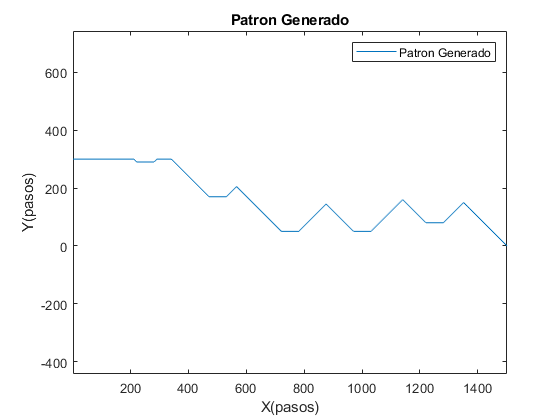

plot(yf)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(pasos)")
ylabel("Y(pasos)")

## Simulacion

Modelo DH

%%clear all
%%close all
syms l theta
L = 6;
L01 = Link('theta',pi/2,'a',0,'alpha',pi/2)

 
L01 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=1.5708, offset=0


L02 = Link('theta',pi/2,'a',0,'alpha',0)

 
L02 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=0, offset=0


L1 = Link('theta',0,'a',0,'alpha',0)

 
L1 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0


L2 = Link('d',0,'a',6.5,'alpha',0,'offset',-pi/2+60*pi/180)

 
L2 = 
Revolute(std): theta=q, d=0, a=6.5, alpha=0, offset=-0.523599


bot = SerialLink([L01 L02 L1,L2],'name','Maquina')

 
bot = 
 
Maquina:: 4 axis, PPPR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|     1.5708|         q1|          0|     1.5708|          0|
|  2|     1.5708|         q2|          0|          0|          0|
|  3|          0|         q3|          0|          0|          0|
|  4|         q4|          0|        6.5|          0|  -0.523599|
+---+-----------+-----------+-----------+-----------+-----------+
 


Pd = [0 0 10 4*pi/180];
W=[0,15,-10,10,-5,10];
clf
%%bot.plot(Pd,'workspace',W)

Af1= bot.fkine([0 0 10 0]);
pf1 = Af1.t

pf1 =    10.0000
    3.2500
    5.6292


Af2= bot.fkine(Pd);
pf2 = Af2.t

pf2 =    10.0000
    2.8494
    5.8422


diff = pf1(2)-pf2(2)

diff = 0.4006

ycut = 6;
d = 0;
x = 5;
d = 0.5;
y = ycut-d;
theta = acos(y/L);
thetag = acosd(y/L)

thetag = 23.5565


pd = [0 0 x theta] ;
W=[0,4,0,7,-5,6];

xKEY = 0:1500;
yKEY = yf; 

xk = xKEY*(2.7/1500);
thetak = -yKEY*((4.2*pi/180)/(12*32));
C = zeros(1,3)

C =      0     0     0


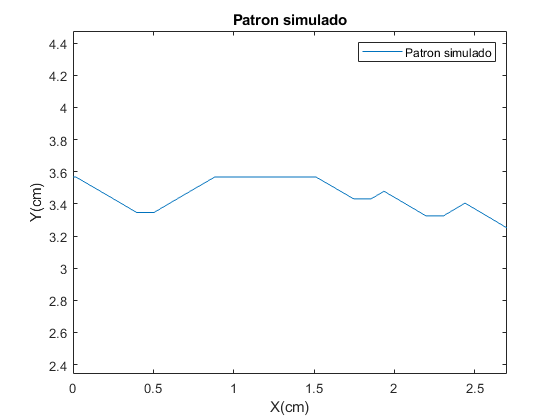


for i = 1:length(xk)
    A = bot.fkine([0 0 xk(i) thetak(i)]);
    Xp = A.t(1);
    Yp = A.t(2);
    C(i,:) = [Xp Yp 0];
    
%     if mod(i,10)==0
%             clf
%             figure(1)
%             bot.plot([0 0 xk(i) thetak(i)],'workspace',W)
%             view(-90,0)
%     end

    %figure(2)
    %plot(C(:,1),C(:,2))
    
end
close all
plot(C(:,1),C(:,2))
axis("equal")
title("Patron simulado")
legend("Patron simulado")
xlabel("X(cm)")
ylabel("Y(cm)")

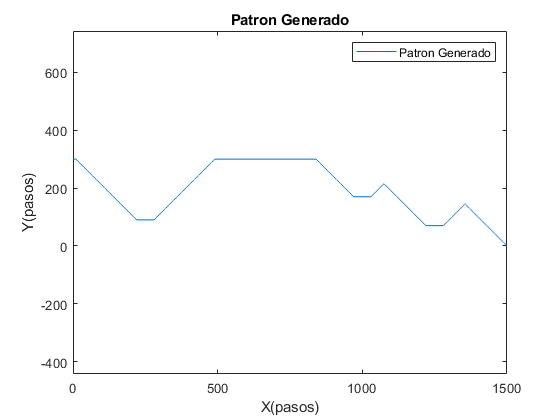

clf
plot(xKEY,yKEY)
axis("equal")
legend("Patron Generado")
title("Patron Generado")
xlabel("X(pasos)")
ylabel("Y(pasos)")

max(C(:,2))-min(C(:,2))

ans = 0.3169